% Load the Excel file
filename = 'C:\Users\nanig\OneDrive\Desktop\project\HWY.xlsx'; % Replace with your Excel file name
data = readtable(filename);

% Display the first few rows of the data
disp(data)

    Time_s_    Local_PC_Time_s_    Dyno_Spd_mph_    Dyno_TractiveForce_N_    Dyno_LoadCell_N_    Distance_mi_    Dyno_Spd_Front_mph_    Dyno_TractiveForce_Front_N_    Dyno_LoadCell_Front_N_    Dyno_Spd_Rear_mph_    Dyno_LoadCell_Rear_N_    Dyno_TractiveForce_Rear_N_    DilAir_RH___    Tailpipe_Press_inH2O_    Cell_Temp_C_    Cell_RH___    Cell_Press_inHg_    Front_Tire_Temp_C_    Fan_Air_Spd_mph_    Rear_TireTemp_C_    Drive_Schedule_Time_s_    Drive_Trace_Schedule_MPH_    Exhaust_Bag    DeltaT_s_    Local_Master_Time_s_    Local_PC_Time_s__RawFuelScale2

% Get the number of rows and columns in the dataset
[numRows, numCols] = size(data);

% Display the shape of the dataset
fprintf('The dataset has %d rows and %d columns.\n', numRows, numCols);

The dataset has 15551 rows and 113 columns.


disp(data.Properties.VariableNames);  % Display column names

    {'Time_s_'}    {'Local_PC_Time_s_'}    {'Dyno_Spd_mph_'}    {'Dyno_TractiveForce_N_'}    {'Dyno_LoadCell_N_'}    {'Distance_mi_'}    {'Dyno_Spd_Front_mph_'}    {'Dyno_TractiveForce_Front_N_'}    {'Dyno_LoadCell_Front_N_'}    {'Dyno_Spd_Rear_mph_'}    {'Dyno_LoadCell_Rear_N_'}    {'Dyno_TractiveForce_Rear_N_'}    {'DilAir_RH___'}    {'Tailpipe_Press_inH2O_'}    {'Cell_Temp_C_'}    {'Cell_RH___'}    {'Cell_Press_inHg_'}    {'Front_Tire_Temp_C_'}    {'Fan_Air_Spd_mph_'}    {'Rear_TireTemp_C_'}    {'Drive_Schedule_Time_s_'}    {'Drive_Trace_Schedule_MPH_'}    {'Exhaust_Bag'}    {'DeltaT_s_'}    {'Local_Master_Time_s_'}    {'Local_PC_Time_s__RawFuelScale2'}    {'Eng_Fuel_Direct_L_'}    {'Eng_FuelFlow_Direct_cc_s_'}    {'Eng_FuelTemp_Direct_C_'}    {'Local_Master_Time_s__RawVehicleDAQ'}    {'Local_PC_Time_s__RawVehicleDAQ'}    {'Eng_Oil_Dipstick_Temp_C_'}    {'Radiator_AirFlow_Temp_C_'}    {'Engine_Bay_Temp_C_'}    {'Heater_Core_Hose_Temp_C_'}    {'Cabin_Temp_C_'}    {'Cabin_Vent_Temp_C_



% Select relevant columns (Time, Engine Features, Battery Features, Driving Conditions)
selectedColumns = {'Time_s_', 'Eng_Spd_CAN_rpm_', 'Eng_Torq_CAN_Nm_', ...
    'Eng_FuelFlow_Direct_cc_s_', 'Eng_FuelTemp_Direct_C_', 'Eng_Clnt_Temp_CAN_C_', ...
    'Eng_Oil_Dipstick_Temp_C_', 'Batt_Volt_CAN_V_', 'Batt_Current_CAN_A_', ...
    'Brake_Press_CAN_kPa_', 'Pedal_Accel_Pos_CAN___', 'Vehicle_Speed_CAN_mph_', ...
    'Trans_Gear_Act_CAN__'};

% Extract relevant data
filteredData = data(:, selectedColumns);

% Display first few rows
disp('Filtered Dataset Preview:');

Filtered Dataset Preview:


disp(head(filteredData));

    Time_s_    Eng_Spd_CAN_rpm_    Eng_Torq_CAN_Nm_    Eng_FuelFlow_Direct_cc_s_    Eng_FuelTemp_Direct_C_    Eng_Clnt_Temp_CAN_C_    Eng_Oil_Dipstick_Temp_C_    Batt_Volt_CAN_V_    Batt_Current_CAN_A_    Brake_Press_CAN_kPa_    Pedal_Accel_Pos_CAN___    Vehicle_Speed_CAN_mph_    Trans_Gear_Act_CAN__
    _______    ________________    ________________    _________________________    ______________________    ____________________    ________________________    ________________    ___________________    ____________________    ______________________    ______________________

% Extract individual variables
t = filteredData.Time_s_;  % Time vector
engine_rpm = filteredData.Eng_Spd_CAN_rpm_;  % Engine Speed (RPM)
battery_voltage = filteredData.Batt_Volt_CAN_V_;  % Battery Voltage (V)

% Save the filtered dataset for future use
writetable(filteredData, 'filtered_data_output.csv');

disp('Filtered dataset saved as filtered_data_output.csv');

Filtered dataset saved as filtered_data_output.csv


filename = 'filtered_data_output.csv'; % Replace with your Excel file name
data = readtable(filename);
disp(data)

    Time_s_    Eng_Spd_CAN_rpm_    Eng_Torq_CAN_Nm_    Eng_FuelFlow_Direct_cc_s_    Eng_FuelTemp_Direct_C_    Eng_Clnt_Temp_CAN_C_    Eng_Oil_Dipstick_Temp_C_    Batt_Volt_CAN_V_    Batt_Current_CAN_A_    Brake_Press_CAN_kPa_    Pedal_Accel_Pos_CAN___    Vehicle_Speed_CAN_mph_    Trans_Gear_Act_CAN__
    _______    ________________    ________________    _________________________    ______________________    ____________________    ________________________    ________________    ___________________    ____________________    ______________________    ______________________

% Get the number of rows and columns in the dataset
[numRows, numCols] = size(data);

% Display the shape of the dataset
fprintf('The dataset has %d rows and %d columns.\n', numRows, numCols);

The dataset has 15551 rows and 13 columns.


disp(data.Properties.VariableNames);  % Display column names

    {'Time_s_'}    {'Eng_Spd_CAN_rpm_'}    {'Eng_Torq_CAN_Nm_'}    {'Eng_FuelFlow_Direct_cc_s_'}    {'Eng_FuelTemp_Direct_C_'}    {'Eng_Clnt_Temp_CAN_C_'}    {'Eng_Oil_Dipstick_Temp_C_'}    {'Batt_Volt_CAN_V_'}    {'Batt_Current_CAN_A_'}    {'Brake_Press_CAN_kPa_'}    {'Pedal_Accel_Pos_CAN___'}    {'Vehicle_Speed_CAN_mph_'}    {'Trans_Gear_Act_CAN__'}




% Extract relevant columns for anomaly detection
t = data.("Time_s_");  % Time vector
engine_rpm = data.("Eng_Spd_CAN_rpm_");  % Engine Speed (RPM)
battery_voltage = data.("Batt_Volt_CAN_V_");  % Battery Voltage (V)

% Ensure voltage never goes below 48V. This step helps to avoid false alarms
battery_voltage(battery_voltage < 48) = 48;

% prepares the data for analysis or modeling by defining features (X) and target (Y)
X = [battery_voltage, t];  % Features: battery voltage and time
Y = engine_rpm;  % Target: engine RPM

% Split data into training and testing sets
cv = cvpartition(length(Y), 'HoldOut', 0.3);  % 70% training, 30% testing
XTrain = X(training(cv), :);
YTrain = Y(training(cv));
XTest = X(test(cv), :);
YTest = Y(test(cv));

% Normalize features (SVR works better with normalized data)
XTrain = normalize(XTrain);
XTest = normalize(XTest);

% Train a Support Vector Regression model
svrModel = fitrsvm(XTrain, YTrain, 'KernelFunction', 'rbf', 'Standardize', true);

% Predict on test data
YPred = predict(svrModel, XTest);

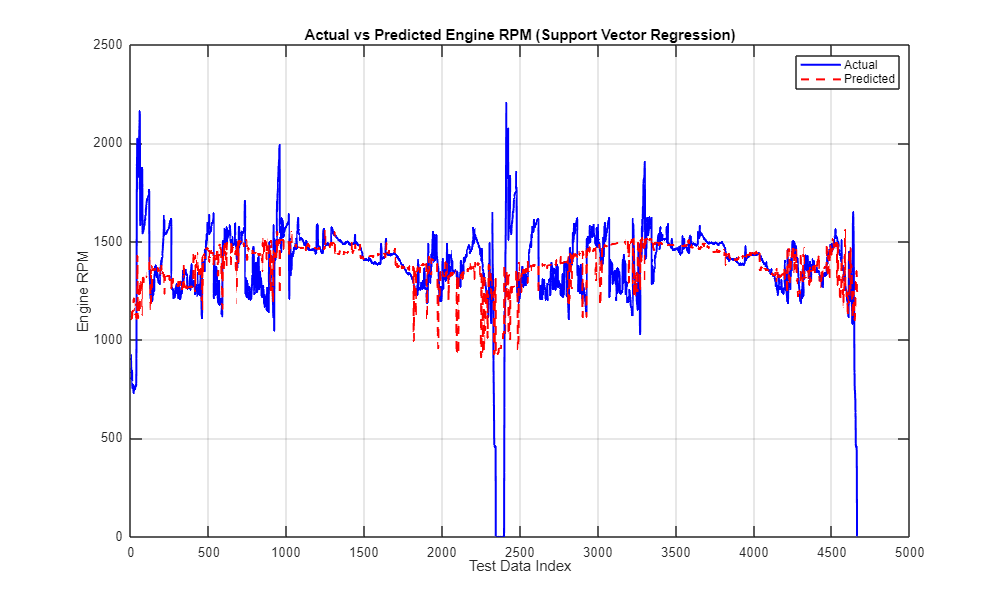

% Plot actual vs predicted values
figure('Position', [100, 100, 1000, 600]); % Resize figure for better visibility
plot(YTest, 'b-', 'LineWidth', 1.5);
hold on;
plot(YPred, 'r--', 'LineWidth', 1.5);
xlabel('Test Data Index');
ylabel('Engine RPM');
title('Actual vs Predicted Engine RPM (Support Vector Regression)');
legend('Actual', 'Predicted');
grid on;

% Mean Squared Error (MSE)
mse = mean((YTest - YPred).^2);
disp(['Mean Squared Error (MSE): ', num2str(mse)]);

Mean Squared Error (MSE): 36272.5437



% Root Mean Squared Error (RMSE)
rmse = sqrt(mse);
disp(['Root Mean Squared Error (RMSE): ', num2str(rmse)]);

Root Mean Squared Error (RMSE): 190.4535



% Mean Absolute Error (MAE)
mae = mean(abs(YTest - YPred));
disp(['Mean Absolute Error (MAE): ', num2str(mae)]);

Mean Absolute Error (MAE): 106.3352


mape = mean(abs((YTest - YPred) ./ YTest)) * 100;
disp(['Mean Absolute Percentage Error (MAPE): ', num2str(mape), '%']);

Mean Absolute Percentage Error (MAPE): Inf%


% Compute mean and standard deviation from normal data
rpm_mean = mean(engine_rpm);
rpm_std = std(engine_rpm);
voltage_mean = mean(battery_voltage);
voltage_std = std(battery_voltage);
% Dynamic thresholding for 48V MHEV
rpm_threshold = rpm_mean + 3 * rpm_std;   % RPM exceeds this → anomaly
rpm_std_threshold = 1.5 * rpm_std;        % RPM fluctuation too high → anomaly
voltage_low = 42;                         % Lower voltage limit for 48V MHEV
voltage_high = 54;                        % Upper voltage limit for 48V MHEV

% Initialize labels array with zeros
labels = zeros(size(engine_rpm));  % Same length as data

% Loop through each data point to classify it
for i = 1:length(engine_rpm)
    if engine_rpm(i) > rpm_threshold || abs(engine_rpm(i) - rpm_mean) > rpm_std_threshold || ...
       battery_voltage(i) < voltage_low || battery_voltage(i) > voltage_high
        labels(i) = 1;  % Anomaly
    else
        labels(i) = 0;  % Normal
    end
end

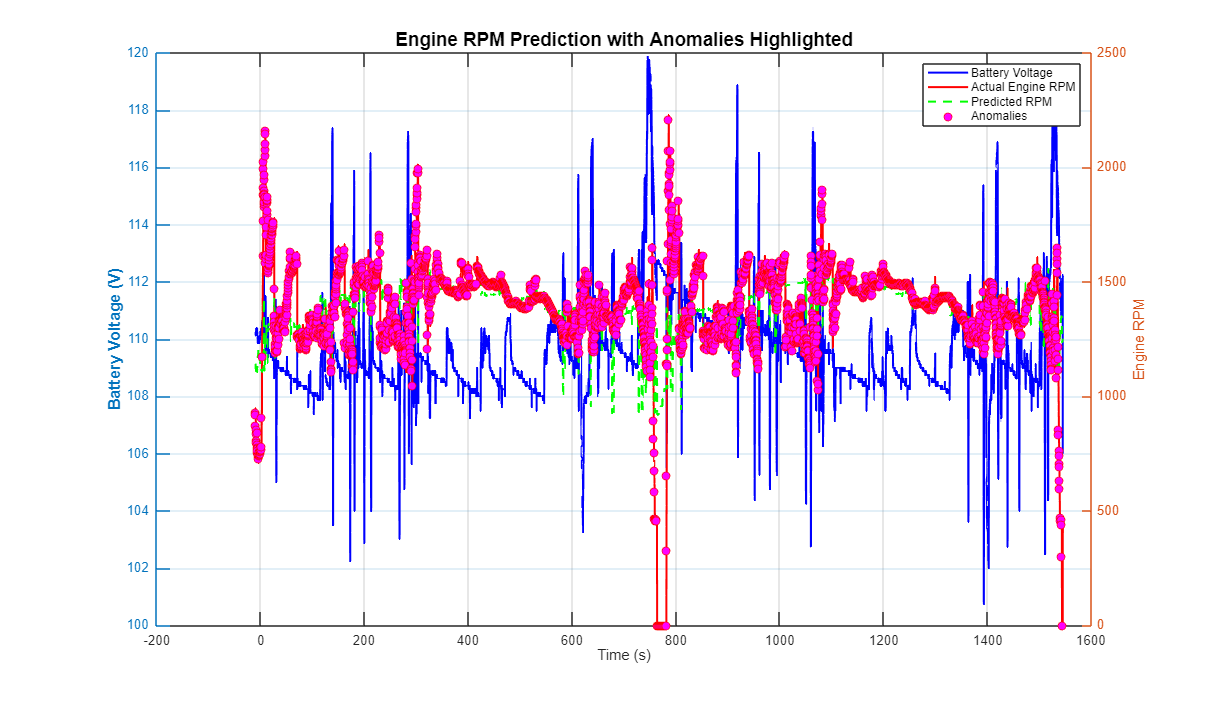

% Resize the figure for better visibility
figure('Position', [100, 100, 1200, 700]); % Adjusted figure size

yyaxis left
plot(t, battery_voltage, 'b', 'LineWidth', 1.5);
ylabel('Battery Voltage (V)', 'FontSize', 12, 'FontWeight', 'bold');

yyaxis right
plot(t, engine_rpm, 'r', 'LineWidth', 1.5);
hold on;
plot(t(test(cv)), YPred, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Predicted RPM');

% Labels and title
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
title('Engine RPM and Battery Voltage with Predicted Anomalies', 'FontSize', 14, 'FontWeight', 'bold');

% Improve visibility
grid on;
% Ensure anomalies are computed
anomalies = find(engine_rpm > rpm_threshold | engine_rpm < (rpm_mean - 3 * rpm_std) | ...
                 battery_voltage < voltage_low | battery_voltage > voltage_high);

% Ensure anomalies are within valid range
if isempty(anomalies)
    warning('No anomalies detected.');
    return; % Stop execution to prevent errors
end

% Extract time values for test dataset
test_indices = find(test(cv));  % Ensure valid test indices
anomaly_times = t(test_indices); 

% Ensure anomalies do not exceed available test indices
valid_indices = anomalies(anomalies <= length(anomaly_times));
anomaly_times = anomaly_times(valid_indices);
anomaly_rpm = YTest(valid_indices);

% Plot anomalies
hold on;
plot(anomaly_times, anomaly_rpm, 'ro', 'MarkerFaceColor', 'm', 'DisplayName', 'Anomalies');

% Labels and title
ylabel('Engine RPM');
xlabel('Time (s)');
title('Engine RPM Prediction with Anomalies Highlighted');
legend('Battery Voltage', 'Actual Engine RPM', 'Predicted RPM', 'Anomalies');
grid on;
hold off;


% Define parameters for the moving window
window_size = 100;  % Number of samples per window
step_size = 10;  % Step size for the moving window


% Initialize storage for features and labels
rpm_features_all = [];
voltage_features_all = [];
timestamps = [];
num_windows = floor((length(t) - window_size) / step_size) + 1;  % Calculate number of windows
labels = zeros(num_windows, 1);  % Preallocate labels

% Loop through data with a moving window
window_index = 1; % Index for storing labels
for i = 1:step_size:(length(t) - window_size + 1)  % Prevent out-of-bounds error
    % Define the window range
    window_range = i:(i + window_size - 1);
    current_time = mean(t(window_range));
    
    % Extract RPM and Voltage features within the window
    rpm_window = engine_rpm(window_range);
    voltage_window = battery_voltage(window_range);
    
    % Statistical features for RPM
    rpm_percentiles = prctile(rpm_window, [10, 25, 50, 75, 90]);
    rpm_mean = mean(rpm_window);
    rpm_std = std(rpm_window);
    rpm_features = [rpm_percentiles, rpm_mean, rpm_std];
    
    % Statistical features for Battery Voltage
    voltage_percentiles = prctile(voltage_window, [10, 25, 50, 75, 90]);
    voltage_mean = mean(voltage_window);
    voltage_std = std(voltage_window);
    voltage_features = [voltage_percentiles, voltage_mean, voltage_std];
    
    % Store extracted features and current time
    rpm_features_all = [rpm_features_all; rpm_features];
    voltage_features_all = [voltage_features_all; voltage_features];
    timestamps = [timestamps; current_time];
    
    % Compute dynamic thresholds
    rpm_threshold = rpm_mean + 3 * rpm_std;  % Anomalous if RPM exceeds this
    rpm_std_threshold = 1.5 * rpm_std;       % Anomalous if RPM fluctuation is too high
    voltage_low = 42;                        % Lower limit of battery voltage
    voltage_high = 54.0;                     % Upper limit of battery voltage

    % Label anomalies based on dynamic conditions
    if any(rpm_window > rpm_threshold) || any(abs(rpm_window - rpm_mean) > rpm_std_threshold) || ...
       any(voltage_window < voltage_low) || any(voltage_window > voltage_high)
        labels(window_index) = 1;  % 1 for anomaly
    else
        labels(window_index) = 0;  % 0 for normal
    end
    
    window_index = window_index + 1; % Move to the next label index
end




% Combine voltage and RPM features for anomaly classification
X = [voltage_features_all, rpm_features_all];
Y = labels;  % Labels for classification
% Split data into training and testing sets
cv = cvpartition(length(Y), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
YTrain = Y(training(cv));
XTest = X(test(cv), :);
YTest = Y(test(cv));
% Normalize features for SVR
XTrain = normalize(XTrain);
XTest = normalize(XTest);

% Train a Support Vector Classifier
svrModel = fitrsvm(XTrain, YTrain, 'KernelFunction', 'rbf', 'Standardize', true);
% Predict on test data and calculate metrics
YPred = predict(svrModel, XTest);
YPred = round(YPred);  % Round predictions to nearest integer (0 or 1)

% Calculate evaluation metrics
TP = sum((YTest == 1) & (YPred == 1));  % True Positives
FP = sum((YTest == 0) & (YPred == 1));  % False Positives
FN = sum((YTest == 1) & (YPred == 0));  % False Negatives
TN = sum((YTest == 0) & (YPred == 0));  % True Negatives

precision = TP / (TP + FP + eps);  % Precision (avoid division by zero)
recall = TP / (TP + FN + eps);  % Recall (avoid division by zero)
accuracy = (TP + TN) / (TP + TN + FP + FN);  % Accuracy formula

% Display results
disp(['Precision: ', num2str(precision)]);

Precision: 1


disp(['Recall: ', num2str(recall)]);

Recall: 1


disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 1


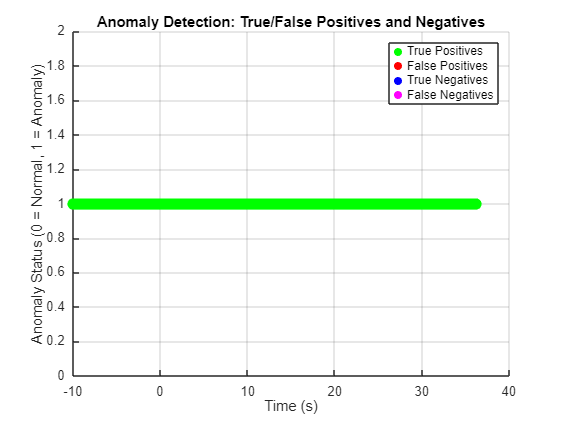

% Generate some sample data if not already available
% t = linspace(0, 100, length(YTest)); % Assuming time vector exists

% Identify different cases
true_positive = (YTest == 1) & (YPred == 1);  % Correctly detected anomalies
false_positive = (YTest == 0) & (YPred == 1); % Wrongly flagged normal as anomaly
true_negative = (YTest == 0) & (YPred == 0);  % Correctly detected normal cases
false_negative = (YTest == 1) & (YPred == 0); % Missed actual anomalies

% Plot results
figure;
hold on;
scatter(t(true_positive), YTest(true_positive), 70, 'g', 'filled', 'DisplayName', 'True Positives');
scatter(t(false_positive), YTest(false_positive), 70, 'r', 'filled', 'DisplayName', 'False Positives');
scatter(t(true_negative), YTest(true_negative), 70, 'b', 'filled', 'DisplayName', 'True Negatives');
scatter(t(false_negative), YTest(false_negative), 70, 'm', 'filled', 'DisplayName', 'False Negatives');

% Labels and Title
xlabel('Time (s)');
ylabel('Anomaly Status (0 = Normal, 1 = Anomaly)');
title('Anomaly Detection: True/False Positives and Negatives');
legend;
grid on;
hold off;

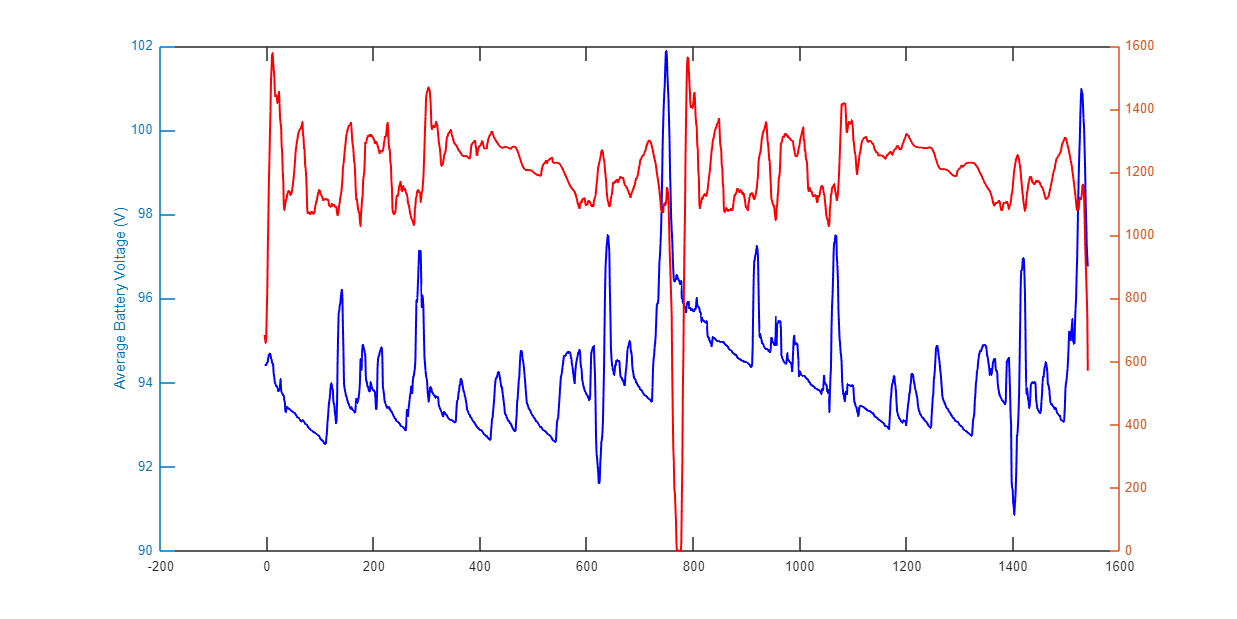

% Visualize anomalies over time with battery voltage and engine RPM
figure('Position', [100, 100, 1400, 700]); % Resized for better visibility

yyaxis left
plot(timestamps, mean(voltage_features_all, 2), 'b', 'LineWidth', 1.5);
ylabel('Average Battery Voltage (V)');

yyaxis right
plot(timestamps, mean(rpm_features_all, 2), 'r', 'LineWidth', 1.5);
hold on;

% Mean Squared Error (MSE)
mse = mean((YTest - YPred).^2);
disp(['Mean Squared Error (MSE): ', num2str(mse)]);

Mean Squared Error (MSE): 0



% Root Mean Squared Error (RMSE)
rmse = sqrt(mse);
disp(['Root Mean Squared Error (RMSE): ', num2str(rmse)]);

Root Mean Squared Error (RMSE): 0



% Mean Absolute Error (MAE)
mae = mean(abs(YTest - YPred));
disp(['Mean Absolute Error (MAE): ', num2str(mae)]);

Mean Absolute Error (MAE): 0


mape = mean(abs((YTest - YPred) ./ YTest)) * 100;
disp(['Mean Absolute Percentage Error (MAPE): ', num2str(mape), '%']);

Mean Absolute Percentage Error (MAPE): 0%


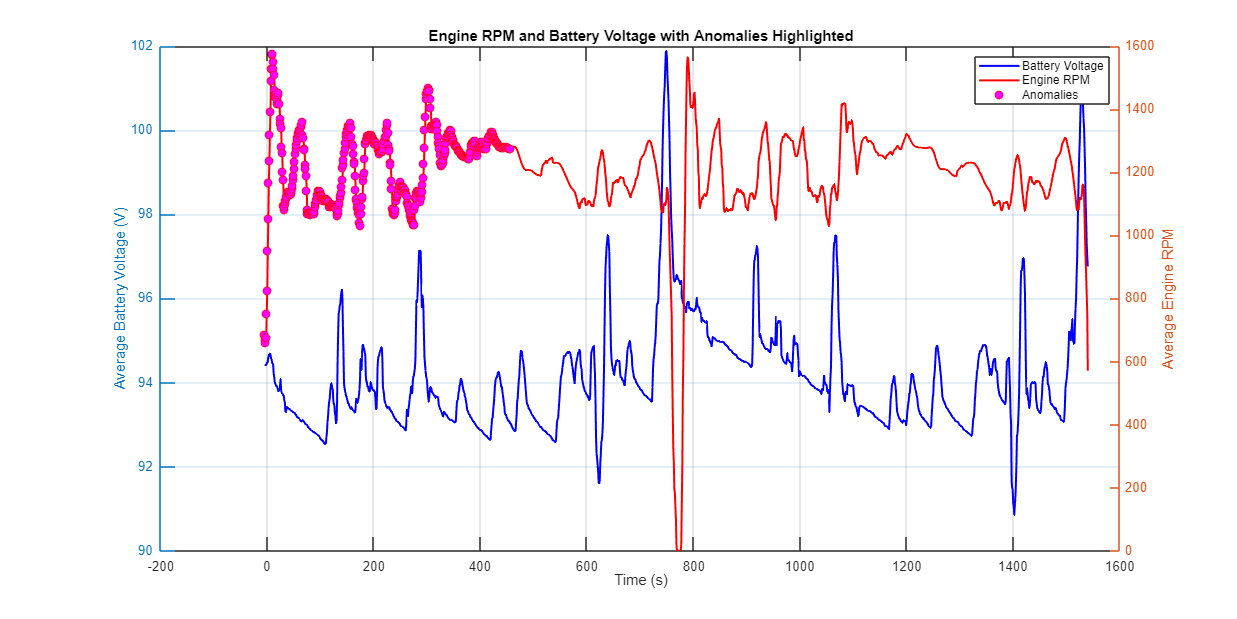

% Identify anomaly times
anomaly_times = timestamps(YTest == 1);

% Plot anomalies
plot(anomaly_times, mean(rpm_features_all(YTest == 1, :), 2), 'ro', 'MarkerFaceColor', 'm');
ylabel('Average Engine RPM');
xlabel('Time (s)');
title('Engine RPM and Battery Voltage with Anomalies Highlighted');
legend('Battery Voltage', 'Engine RPM', 'Anomalies');
grid on;

% Initialize storage for features and timestamps
rpm_features_all = [];
voltage_features_all = [];
timestamps = [];
% Loop through data with a moving window
for i = 1:step_size:(length(t) - window_size)
    % Define the window range
    window_range = i:i + window_size - 1;
    current_time = mean(t(window_range));
    
    % Store the timestamp
    timestamps = [timestamps; current_time];

    % Extract RPM window
    rpm_window = engine_rpm(window_range);
    rpm_percentiles = prctile(rpm_window, [10, 25, 50, 75, 90]);  
    [pks_rpm, locs_rpm, width_rpm, prominence_rpm] = findpeaks(rpm_window, 'MinPeakProminence', 50);
    mean_peak_rpm = mean(pks_rpm, 'omitnan');
    mean_width_rpm = mean(width_rpm, 'omitnan');
    mean_prominence_rpm = mean(prominence_rpm, 'omitnan');
    mean_time_rpm = mean(locs_rpm, 'omitnan') / window_size;  
    rate_of_peaks_rpm = numel(pks_rpm) / window_size;

    % Combine RPM features
    rpm_features = [rpm_percentiles, mean_peak_rpm, mean_width_rpm, mean_prominence_rpm, mean_time_rpm, rate_of_peaks_rpm];
    rpm_features_all = [rpm_features_all; rpm_features];  

    % Extract Battery Voltage window
    voltage_window = battery_voltage(window_range);
    voltage_percentiles = prctile(voltage_window, [10, 25, 50, 75, 90]);  
    [pks_voltage, locs_voltage, width_voltage, prominence_voltage] = findpeaks(voltage_window, 'MinPeakProminence', 0.05);
    mean_peak_voltage = mean(pks_voltage, 'omitnan');
    mean_width_voltage = mean(width_voltage, 'omitnan');
    mean_prominence_voltage = mean(prominence_voltage, 'omitnan');
    mean_time_voltage = mean(locs_voltage, 'omitnan') / window_size;
    rate_of_peaks_voltage = numel(pks_voltage) / window_size;

    % Combine Voltage features
    voltage_features = [voltage_percentiles, mean_peak_voltage, mean_width_voltage, mean_prominence_voltage, mean_time_voltage, rate_of_peaks_voltage];
    voltage_features_all = [voltage_features_all; voltage_features];  
end

% Normalize features
voltage_features_all = normalize(voltage_features_all);
rpm_features_all = normalize(rpm_features_all);

% Initialize storage for predictions
predicted_rpm_features_all = zeros(size(rpm_features_all));

% Train SVR models for each RPM feature
for feature_idx = 1:size(rpm_features_all, 2)
    svrModel = fitrsvm(voltage_features_all, rpm_features_all(:, feature_idx), ...
        'KernelFunction', 'rbf', 'Standardize', true);
    predicted_rpm_features_all(:, feature_idx) = predict(svrModel, voltage_features_all);
end



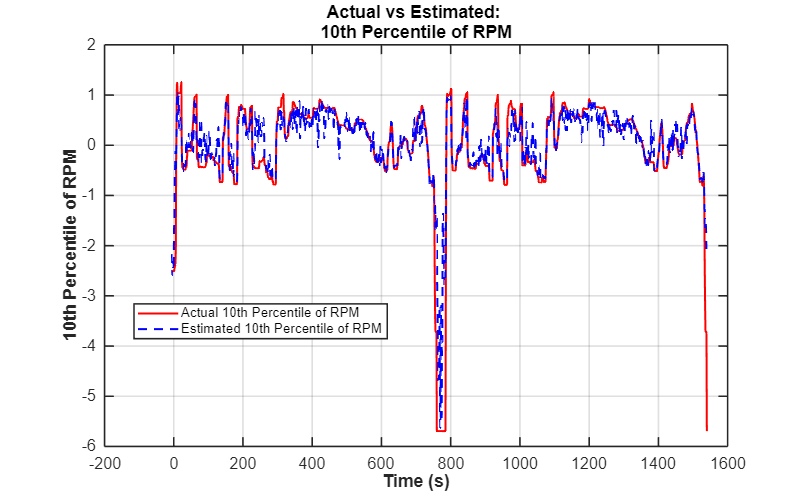

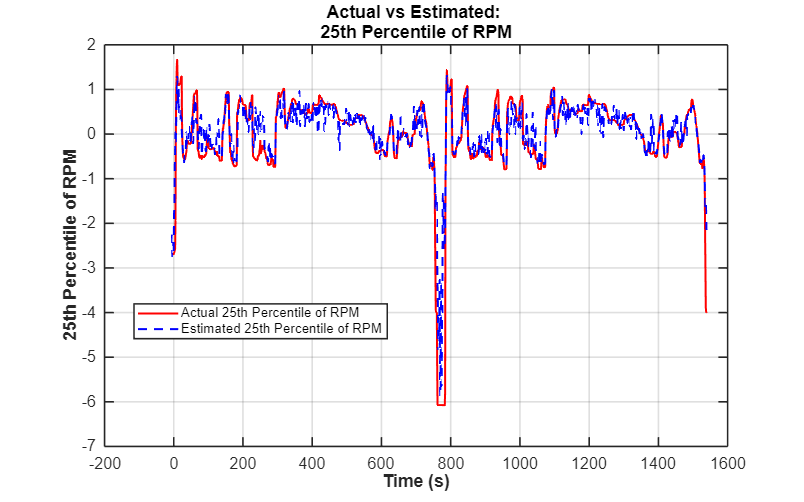

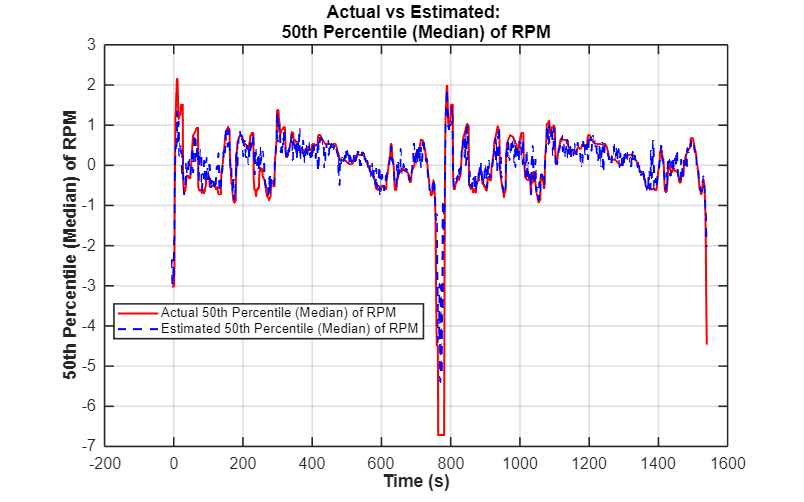

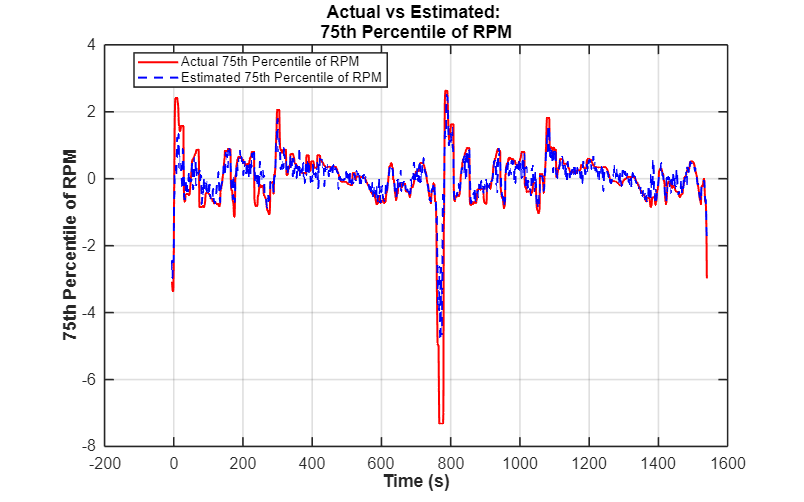

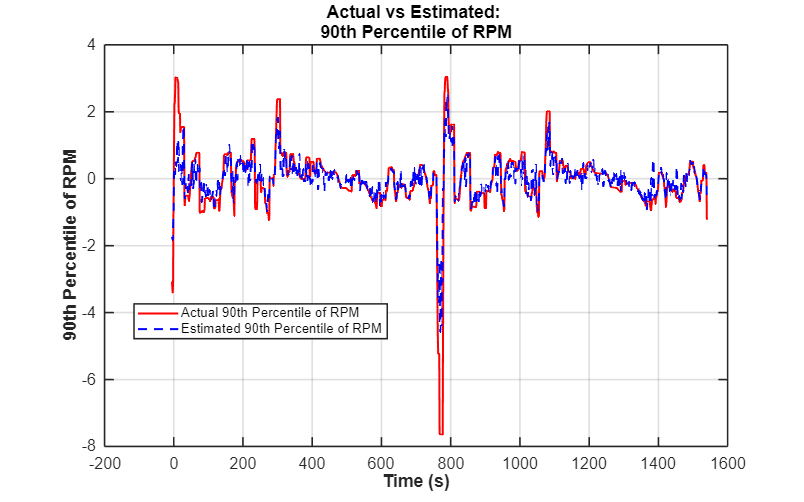

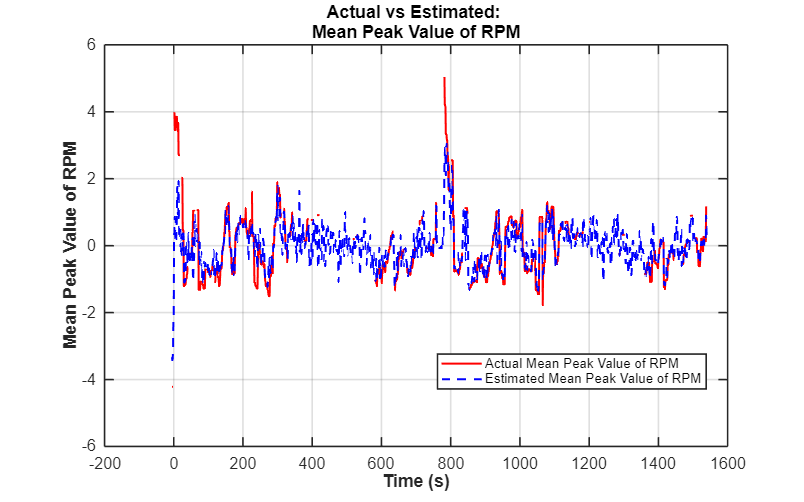

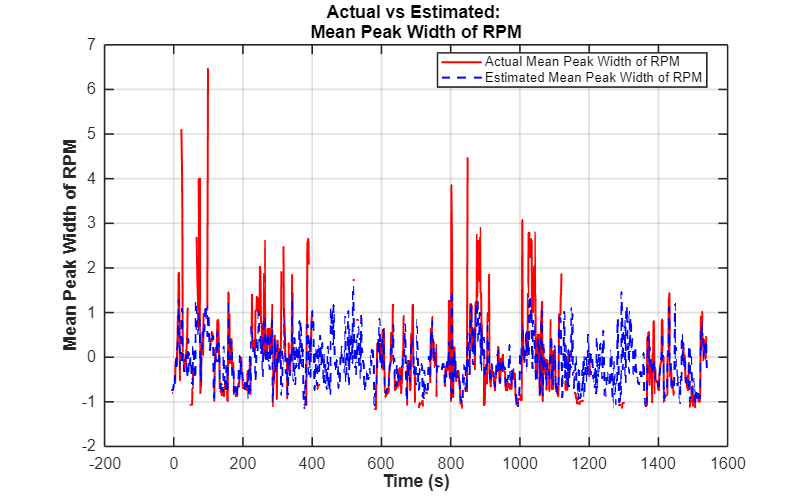

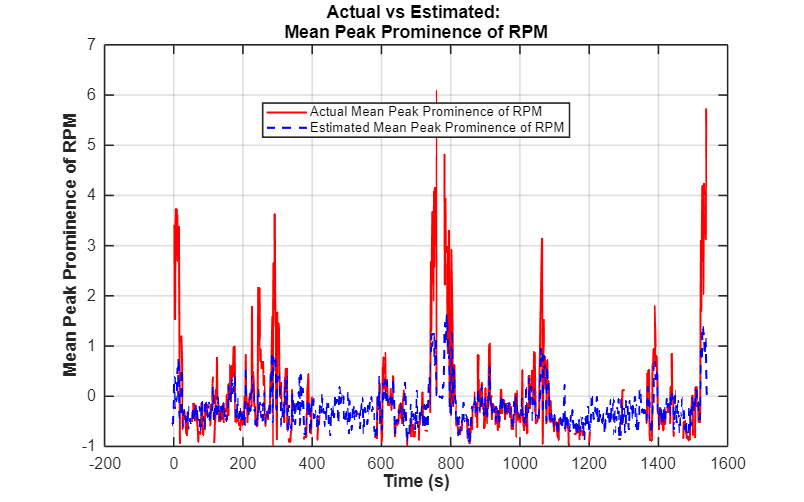


% Define feature names for clarity
feature_names = ["10th Percentile of RPM", "25th Percentile of RPM", "50th Percentile (Median) of RPM", ...
                 "75th Percentile of RPM", "90th Percentile of RPM", "Mean Peak Value of RPM", ...
                 "Mean Peak Width of RPM", "Mean Peak Prominence of RPM", "Mean Time of Peaks in RPM", ...
                 "Rate of Peaks in RPM"];

for i = 1:10
    figure;  % Create a new figure for each feature
    
    % Plot actual vs predicted values
    plot(timestamps, rpm_features_all(:, i), 'r-', 'LineWidth', 1.5); hold on;
    plot(timestamps, predicted_rpm_features_all(:, i), 'b--', 'LineWidth', 1.5);
    
    % Formatting with proper feature names
    xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel(feature_names(i), 'FontSize', 12, 'FontWeight', 'bold');
    title(['Actual vs Estimated: ', feature_names(i)], 'FontSize', 14, 'FontWeight', 'bold');
    
    % Fix: Use proper string conversion for legend
    legend(["Actual " + feature_names(i), "Estimated " + feature_names(i)], 'FontSize', 10, 'Location', 'best');
    grid on;
    
    % Adjust figure layout to avoid overlap issues
    set(gca, 'FontSize', 12, 'LineWidth', 1.2);
    set(gcf, 'Position', [100, 100, 800, 500]); % Resize figure to avoid title overlap
    pause(0.5); % Small pause to let MATLAB render properly
    
    % Fix: Ensure valid filename by replacing spaces and removing invalid characters
    filename = ['Feature_g', num2str(i), '.png'];
    filename = strrep(filename, ' ', '_');  
    filename = regexprep(filename, '[^\w.]', '');  % Remove special characters

    % Save in the current directory
    saveas(gcf, fullfile(pwd, filename));
end

% Initialize storage for features and timestamps
rpm_features_all = [];
voltage_features_all = [];
timestamps = [];

% Loop through data with a moving window
for i = 1:step_size:(length(t) - window_size)
    % Define the window range
    window_range = i:i + window_size - 1;
    current_time = mean(t(window_range));
    
    % Store the timestamp
    timestamps = [timestamps; current_time];

    % Extract RPM window
    rpm_window = engine_rpm(window_range);
    rpm_percentiles = prctile(rpm_window, [10, 25, 50, 75, 90]);  
    [pks_rpm, locs_rpm, width_rpm, prominence_rpm] = findpeaks(rpm_window, 'MinPeakProminence', 50);

    % Handle missing values using moving average with window_size
    pks_rpm = fillmissing(pks_rpm, 'movmean', window_size);
    width_rpm = fillmissing(width_rpm, 'movmean', window_size);
    prominence_rpm = fillmissing(prominence_rpm, 'movmean', window_size);
    locs_rpm = fillmissing(locs_rpm, 'movmean', window_size);

    mean_peak_rpm = mean(pks_rpm, 'omitnan'); 
    mean_width_rpm = mean(width_rpm, 'omitnan'); 
    mean_prominence_rpm = mean(prominence_rpm, 'omitnan'); 
    mean_time_rpm = mean(locs_rpm, 'omitnan') / window_size; 
    rate_of_peaks_rpm = numel(pks_rpm) / window_size;

    % Combine RPM features
    rpm_features = [rpm_percentiles, mean_peak_rpm, mean_width_rpm, mean_prominence_rpm, mean_time_rpm, rate_of_peaks_rpm];
    rpm_features_all = [rpm_features_all; rpm_features];  

    % Extract Battery Voltage window
    voltage_window = battery_voltage(window_range);
    voltage_percentiles = prctile(voltage_window, [10, 25, 50, 75, 90]);  
    [pks_voltage, locs_voltage, width_voltage, prominence_voltage] = findpeaks(voltage_window, 'MinPeakProminence', 0.05);

    % Handle missing values using moving average with window_size
    pks_voltage = fillmissing(pks_voltage, 'movmean', window_size);
    width_voltage = fillmissing(width_voltage, 'movmean', window_size);
    prominence_voltage = fillmissing(prominence_voltage, 'movmean', window_size);
    locs_voltage = fillmissing(locs_voltage, 'movmean', window_size);

    mean_peak_voltage = mean(pks_voltage, 'omitnan'); 
    mean_width_voltage = mean(width_voltage, 'omitnan'); 
    mean_prominence_voltage = mean(prominence_voltage, 'omitnan'); 
    mean_time_voltage = mean(locs_voltage, 'omitnan') / window_size;
    rate_of_peaks_voltage = numel(pks_voltage) / window_size;

    % Combine Voltage features
    voltage_features = [voltage_percentiles, mean_peak_voltage, mean_width_voltage, mean_prominence_voltage, mean_time_voltage, rate_of_peaks_voltage];
    voltage_features_all = [voltage_features_all; voltage_features];  
end


% Split data into training and testing sets
train_ratio = 0.8;
train_size = floor(train_ratio * length(timestamps));
X_train = voltage_features_all(1:train_size, :);
X_test = voltage_features_all(train_size+1:end, :);
Y_train = rpm_features_all(1:train_size, :);
Y_test = rpm_features_all(train_size+1:end, :);

% Initialize storage for SVR models and predictions
num_features = size(rpm_features_all, 2);
svr_models = cell(num_features, 1);
predicted_rpm_features_all = zeros(size(rpm_features_all));

% Train SVR models on the training set
for feature_idx = 1:num_features
    svr_models{feature_idx} = fitrsvm(X_train, Y_train(:, feature_idx), 'KernelFunction', 'rbf', 'Standardize', true);
    predicted_rpm_features_all(:, feature_idx) = predict(svr_models{feature_idx}, voltage_features_all);
end





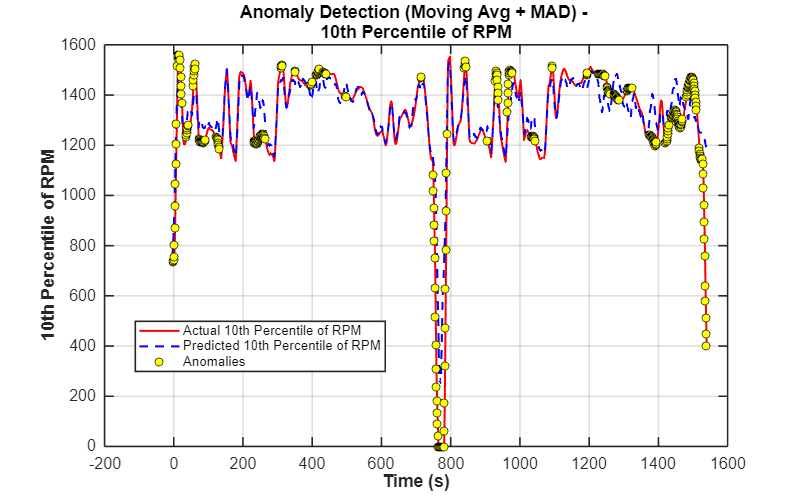

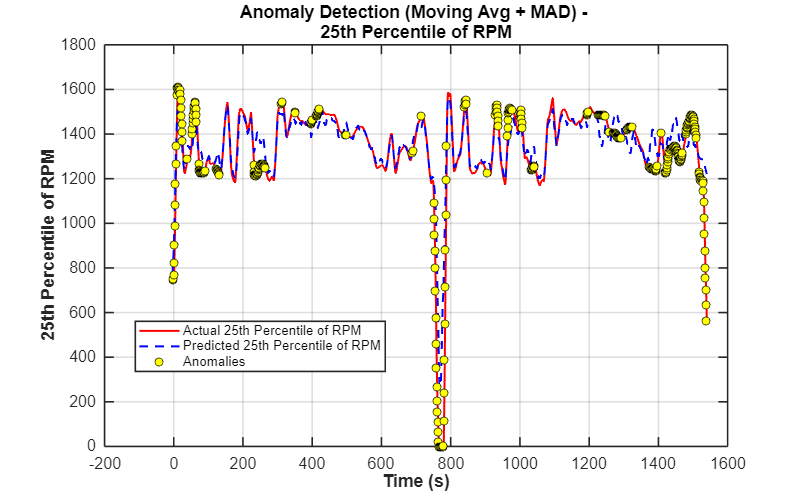

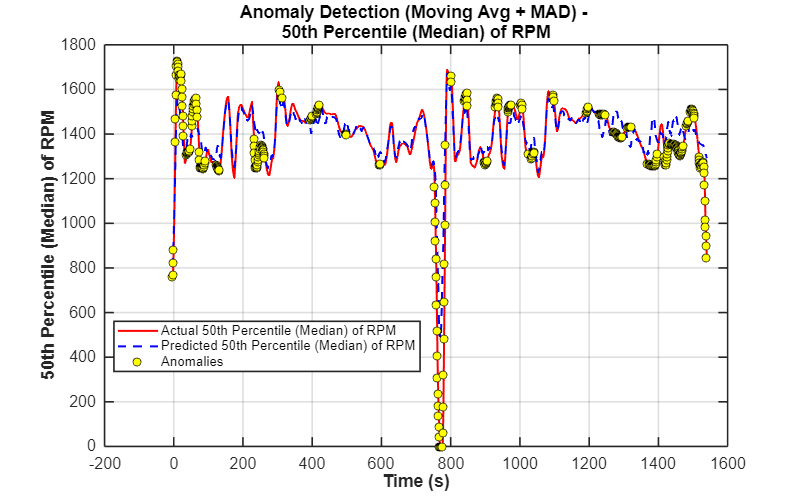

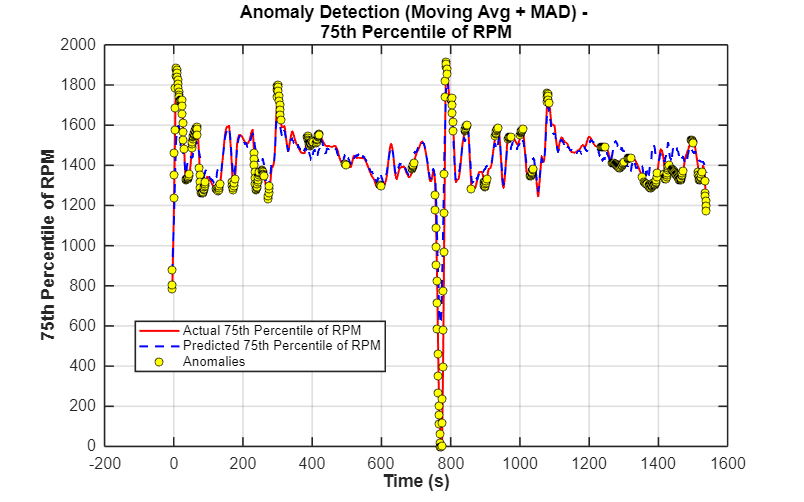

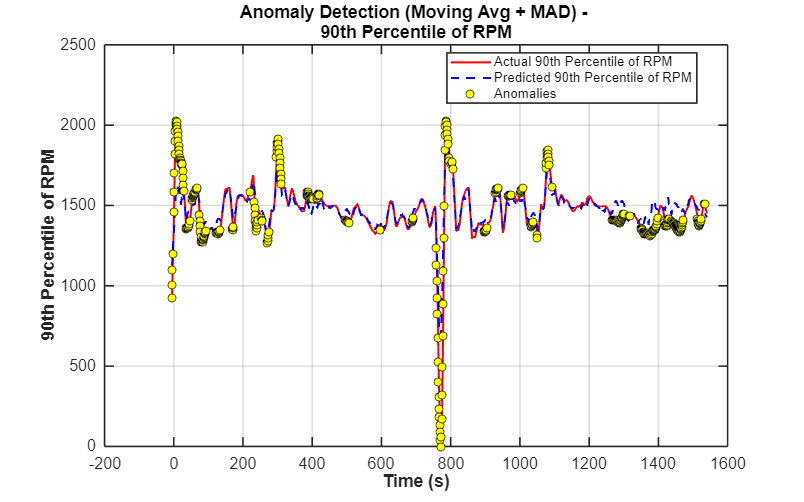

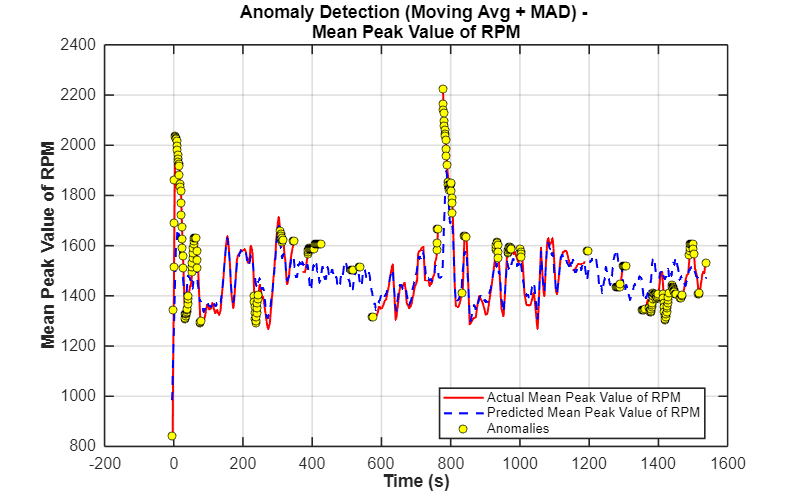

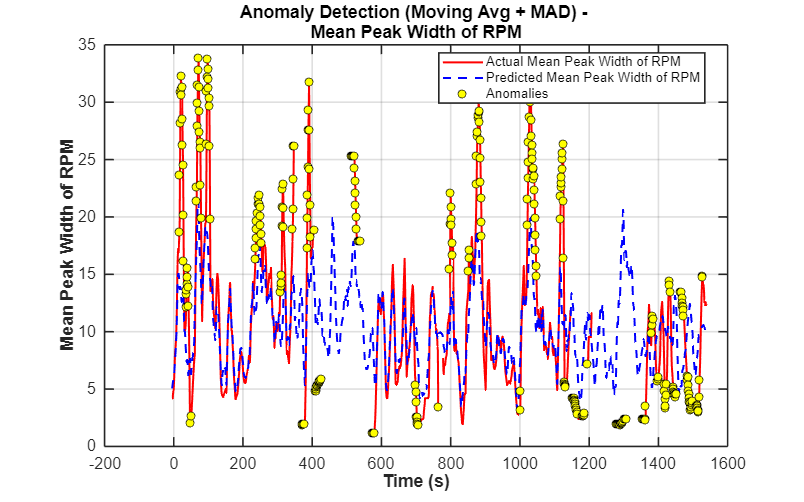

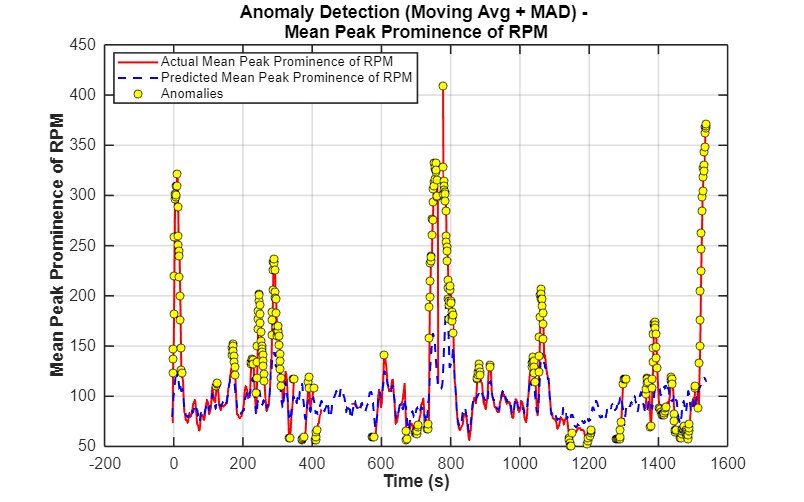

% Define feature names for clarity
feature_names = ["10th Percentile of RPM", "25th Percentile of RPM", "50th Percentile (Median) of RPM", ...
                 "75th Percentile of RPM", "90th Percentile of RPM", "Mean Peak Value of RPM", ...
                 "Mean Peak Width of RPM", "Mean Peak Prominence of RPM", "Mean Time of Peaks in RPM", ...
                 "Rate of Peaks in RPM"];

window_size = 10; % Moving average window size to handle missing values
threshold_factor = 1.5; % Multiplier for adaptive thresholding (MAD method)

for i = 1:10
    figure; % Create a new figure for each feature
    
    % Apply moving average to handle missing values
    smooth_actual = movmean(rpm_features_all(:, i), window_size, 'omitnan');
    smooth_predicted = movmean(predicted_rpm_features_all(:, i), window_size, 'omitnan');
    
    % Compute absolute error signal
    error_signal = abs(smooth_actual - smooth_predicted);
    
    % Dynamic anomaly threshold using Median Absolute Deviation (MAD)
    median_error = median(error_signal, 'omitnan');
    mad_error = median(abs(error_signal - median_error), 'omitnan'); % MAD computation
    anomaly_threshold = median_error + threshold_factor * mad_error;
    
    % Identify anomalies where error exceeds the threshold
    anomalies = error_signal > anomaly_threshold;
    
    % Extract anomaly values and timestamps
    anomaly_times = timestamps(anomalies);
    anomaly_values = smooth_actual(anomalies);
    
    % Plot actual vs predicted values
    plot(timestamps, smooth_actual, 'r-', 'LineWidth', 1.5); hold on;
    plot(timestamps, smooth_predicted, 'b--', 'LineWidth', 1.5);
    
    % Plot anomalies using your specified style
    plot(anomaly_times, anomaly_values, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Anomaly');
    
    % Formatting with proper feature names
    xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel(feature_names(i), 'FontSize', 12, 'FontWeight', 'bold');
    title(['Anomaly Detection (Moving Avg + MAD) - ', feature_names(i)], 'FontSize', 14, 'FontWeight', 'bold');
    
    % Fix legend issue
    legend(["Actual " + feature_names(i), "Predicted " + feature_names(i), "Anomalies"], ...
        'FontSize', 10, 'Location', 'best');
    
    grid on;
    % Adjust figure layout to avoid overlap issues
    set(gca, 'FontSize', 12, 'LineWidth', 1.2);
    set(gcf, 'Position', [100, 100, 800, 500]); % Resize figure to avoid title overlap
    pause(0.5); % Small pause to let MATLAB render properly
    
    % Fix: Ensure valid filename by replacing spaces and removing invalid characters
    filename = ['Feature_g', num2str(i), '.png'];
    filename = strrep(filename, ' ', '_');  
    filename = regexprep(filename, '[^\w.]', '');  % Remove special characters

    % Save in the current directory
    saveas(gcf, fullfile(pwd, filename));
end

% Calculate evaluation metrics
TP = sum((YTest == 1) & (YPred == 1));  % True Positives
FP = sum((YTest == 0) & (YPred == 1));  % False Positives
FN = sum((YTest == 1) & (YPred == 0));  % False Negatives
TN = sum((YTest == 0) & (YPred == 0));  % True Negatives

precision = TP / (TP + FP + eps);  % Precision (avoid division by zero)
recall = TP / (TP + FN + eps);  % Recall (avoid division by zero)
accuracy = (TP + TN) / (TP + TN + FP + FN);  % Accuracy formula

% Display results
disp(['Precision: ', num2str(precision)]);

Precision: 1


disp(['Recall: ', num2str(recall)]);

Recall: 1


disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 1


% Set fixed seed for reproducibility
rng(42);

% Normalize engine RPM and battery voltage
engine_rpm = normalize(engine_rpm, 'zscore');
battery_voltage = normalize(battery_voltage, 'zscore');

% Calculate dynamic thresholds for anomaly classification
rpm_low = prctile(engine_rpm, 5);    % 5th percentile (Lower RPM threshold)
rpm_high = prctile(engine_rpm, 95);  % 95th percentile (Upper RPM threshold)
rpm_fluctuation_threshold = prctile(abs(engine_rpm - median(engine_rpm, 'omitnan')), 85); % Less strict threshold

voltage_low = prctile(battery_voltage, 5);   % 5th percentile (Lower Voltage)
voltage_high = prctile(battery_voltage, 95); % 95th percentile (Upper Voltage)

% Initialize labels array
labels = zeros(size(engine_rpm)); 

% Classify anomalies dynamically based on thresholds
for i = 1:length(engine_rpm)
    if engine_rpm(i) > rpm_high || engine_rpm(i) < rpm_low || ...
       abs(engine_rpm(i) - median(engine_rpm, 'omitnan')) > rpm_fluctuation_threshold || ...
       battery_voltage(i) < voltage_low || battery_voltage(i) > voltage_high
        labels(i) = 1;  % Anomaly
    else
        labels(i) = 0;  % Normal
    end
end

% Set up 5-fold cross-validation
cv = cvpartition(length(labels), 'KFold', 5); 
accuracy_values = zeros(cv.NumTestSets, 1);
precision_values = zeros(cv.NumTestSets, 1);
recall_values = zeros(cv.NumTestSets, 1);

for fold = 1:cv.NumTestSets
    % Training & Testing Split
    trainIdx = cv.training(fold);
    testIdx = cv.test(fold);
    
    X_train = [engine_rpm(trainIdx), battery_voltage(trainIdx)];
    Y_train = labels(trainIdx);
    X_test = [engine_rpm(testIdx), battery_voltage(testIdx)];
    Y_test = labels(testIdx);

    % Train an SVM classifier with RBF kernel and class weighting
    model = fitcsvm(X_train, Y_train, 'KernelFunction', 'rbf', ...
                    'Standardize', true, 'BoxConstraint', 1, ...
                    'ClassNames', [0, 1], ...
                    'Cost', [0 5; 1 0]);  % Higher penalty for false negatives

    % Predict on test data
    Y_pred = predict(model, X_test);

    % Compute performance metrics
    TP = sum((Y_pred == 1) & (Y_test == 1));
    FP = sum((Y_pred == 1) & (Y_test == 0));
    FN = sum((Y_pred == 0) & (Y_test == 1));
    TN = sum((Y_pred == 0) & (Y_test == 0));

    % Compute evaluation metrics
    accuracy = (TP + TN) / (TP + TN + FP + FN);  
    precision = TP / (TP + FP + eps);  
    recall = TP / (TP + FN + eps);  
    
    % Store results
    accuracy_values(fold) = accuracy;
    precision_values(fold) = precision;
    recall_values(fold) = recall;

    % Display per-fold results
    fprintf('Fold %d - Accuracy: %.2f%%, Precision: %.2f%%, Recall: %.2f%%\n', ...
            fold, accuracy * 100, precision * 100, recall * 100);
end

Fold 1 - Accuracy: 96.50%, Precision: 100.00%, Recall: 83.20%
Fold 2 - Accuracy: 96.46%, Precision: 100.00%, Recall: 83.02%
Fold 3 - Accuracy: 96.75%, Precision: 100.00%, Recall: 84.19%
Fold 4 - Accuracy: 96.46%, Precision: 100.00%, Recall: 82.97%
Fold 5 - Accuracy: 96.98%, Precision: 100.00%, Recall: 85.22%



% Display average performance
fprintf('\nAverage Performance Across Folds:\n');


Average Performance Across Folds:


fprintf('Accuracy: %.2f%%\n', mean(accuracy_values) * 100);

Accuracy: 96.63%


fprintf('Precision: %.2f%%\n', mean(precision_values) * 100);

Precision: 100.00%


fprintf('Recall: %.2f%%\n', mean(recall_values) * 100);

Recall: 83.72%




% Display average performance
fprintf('\nAverage Performance Across 5 Folds:\n');


Average Performance Across 5 Folds:


fprintf('Accuracy: %.2f%%\n', mean(accuracy_values) * 100);

Accuracy: 96.63%


fprintf('Precision: %.2f%%\n', mean(precision_values) * 100);

Precision: 100.00%


fprintf('Recall: %.2f%%\n', mean(recall_values) * 100);

Recall: 83.72%




% Display average performance across folds
fprintf('Average Accuracy: %.2f%%\n', mean(accuracy_values) * 100);

Average Accuracy: 96.63%


fprintf('Average Precision: %.2f%%\n', mean(precision_values) * 100);

Average Precision: 100.00%


fprintf('Average Recall: %.2f%%\n', mean(recall_values) * 100);

Average Recall: 83.72%




% Compute the mean of cross-validation results
mean_accuracy = mean(accuracy_values) * 100;
mean_precision = mean(precision_values) * 100;
mean_recall = mean(recall_values) * 100;


% Display final cross-validation results
fprintf('\nCross-Validation Results:\n');


Cross-Validation Results:


fprintf('Mean Accuracy: %.2f%%\n', mean_accuracy);

Mean Accuracy: 96.63%


fprintf('Mean Precision: %.2f%%\n', mean_precision);

Mean Precision: 100.00%


fprintf('Mean Recall: %.2f%%\n', mean_recall);

Mean Recall: 83.72%


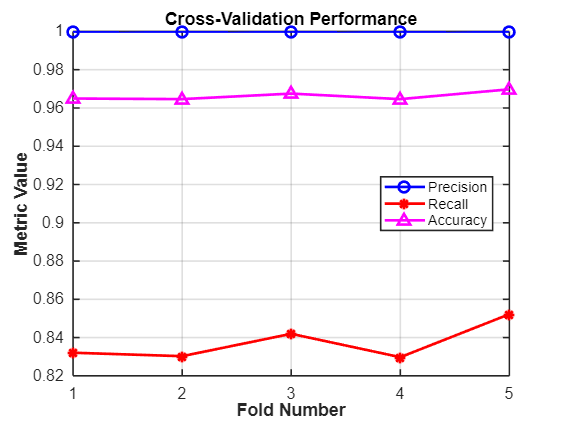



% Plot Cross-Validation Results
figure;
plot(1:cv.NumTestSets, precision_values, 'bo-', 'LineWidth', 2, 'MarkerSize', 8); hold on;
plot(1:cv.NumTestSets, recall_values, 'r*-', 'LineWidth', 2, 'MarkerSize', 8);
plot(1:cv.NumTestSets, accuracy_values, 'm^-', 'LineWidth', 2, 'MarkerSize', 8);

xlabel('Fold Number', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Metric Value', 'FontSize', 12, 'FontWeight', 'bold');
title('Cross-Validation Performance', 'FontSize', 14, 'FontWeight', 'bold');
legend('Precision', 'Recall', 'Accuracy', 'Location', 'best');
grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2);